load HCVEgyptData.mat
disp(HCV)

    Age    Gender    BMI    Fever    NauseaVomting    Headache    Diarrhea    Fatiguegeneralizedboneache    Jaundice    Epigastricpain     WBC        RBC        HGB       Plat       AST1    ALT1    ALT4    ALT12    ALT24    ALT36    ALT48    ALTafter24w     RNABase         RNA4         RNA12         RNAEOT        RNAEF       BaselinehistologicalGrading    Baselinehistologicalstaging
    ___    ______    ___    _____    ________

class(HCV)

ans = 'table'

size(HCV)

ans =         1385          29


sum(sum(ismissing(HCV)))

ans = 0

HCV1=HCV;

# Group data in sets / Discretization

Age 

- Less than 32

- 32-37

- 37-42

- 42-47

- 47-52

- 52-57

- 57-62

Gender, Fever, Nausea/Vomitting, Headache, Diarrhea, Fatigue, Juandice, Epigastricpain, Staging, Grading

for j=1:1385
    
    %Age
    if HCV.Age(j)<32
    HCV1.Age(j)=1;
    else
        if HCV.Age(j)<37
            HCV1.Age(j)=2;
        else 
            if HCV.Age(j)<42
                HCV1.Age(j)=3;
            else
                if HCV.Age(j)<47
                    HCV1.Age(j)=4;
                else
                    if HCV.Age(j)<52
                        HCV1.Age(j)=5;
                    else 
                        if HCV.Age(j)<57
                            HCV1.Age(j)=6;
                        else 
                            if HCV.Age(j)<62
                                HCV1.Age(j)=7;
                            end
                        end
                    end
                end
            end
        end
    end
    
    %BMI
    if HCV1.BMI(j)<18.5
        HCV1.BMI(j)=1;
    else
        if HCV1.BMI(j)<25
            HCV1.BMI(j)=2;
        else
            if HCV1.BMI(j)<30
                HCV1.BMI(j)=3;
            else
                if HCV1.BMI(j)<35
                    HCV1.BMI(j)=4;
                else
                    if HCV1.BMI(j)<40
                        HCV1.BMI(j)=5;
                    end 
                end
            end
        end 
    end
    
    % WBC
    if HCV.WBC(j)<4000
        HCV1.WBC(j)=1;
    else
        if HCV.WBC(j)<11000
            HCV1.WBC(j)=2;
        else
            HCV1.WBC(j)=3;
        end
    end
    
    %RBC
    if HCV.RBC(j)<3000000
        HCV1.RBC(j)=1;
    else
        if HCV.RBC(j)<5000000
            HCV1.RBC(j)=2;
        else
            HCV1.RBC(j)=3;
        end
    end
    
    %Platelet
    if HCV.Plat(j)<100000
        HCV1.Plat(j)=1;
    else 
        if HCV.RBC(j)<255000
            HCV1.Plat(j)=2;
        else
            HCV1.Plat(j)=3;
        end
    end
   
   %HGB
   if HCV.Gender(j)==1
    if HCV.HGB(j)<14
        HCV1.HGB(j)=1;
    else
        if HCV.HGB(j)<17.5
            HCV1.HGB(j)=2;
        else
            HCV1.HGB(j)=3;
        end
    end
   else
    if HCV.HGB(j)<12.3
        HCV1.HGB(j)=4;
    else
        if HCV.HGB(j)<15.3
            HCV1.HGB(j)=5;
        else
            HCV1.HGB(j)=6;
        end
    end
   end
   
   %AST, ALTs
   for i=15:23
    if HCV.(i)(j)<20
        HCV1.(i)(j)=1;
    else
        if HCV.(i)(j)<40
            HCV1.(i)(j)=2;
        else
            HCV1.(i)(j)=3;
        end
    end
   end
   
   %RNAs
   for i=24:27
    if HCV.(i)(j)<=5
        HCV1.(i)(j)=1;
    else
        HCV1.(i)(j)=2;
    end
   end
   
end

## Entire Dataset is categorical now

HCV1

HCV1 = 1385×29 table
    Age    Gender    BMI    Fever    NauseaVomting    Headache    Diarrhea    Fatiguegeneralizedboneache    Jaundice    Epigastricpain    WBC    RBC    HGB    Plat    AST1    ALT1    ALT4    ALT12    ALT24    ALT36    ALT48    ALTafter24w    RNABase    RNA4    RNA12    RNAEOT    RNAEF    BaselinehistologicalGrading    Baselinehistologicalstaging
    ___    ______    ___    _____    _____________   

HCV_array=table2array(HCV1)

HCV_array =      6     1     5     2     1     1     1     2     2     2     2     2     2     3     3     3     3     3     3     1     1     1     3     2     2     1     1    13     2
     4     1     3     1     2     2     1     2     2     1     3     2     1     3     3     3     3     3     3     3     3     3     3     2     2     2     2     4     2
     7     1     4     2     2     2     2     1     1     1     2     2     1     3     3     3     3     3     3     1     1     1     3     2     1     2     2     4     4
     5     2     4     1     2     1     2     1     2     1     2     2     4     3     3     3     3     3     3     3     3     2     3     2     2     2     2    10     3
     7     1     4     1     1     2     1     2     2     2     1     2     1     3     3     3     3     3     3     3     3     2     3     2     2     2     2    11     1
     7     2     2     2     2     2     1     2     2     1     3     2     5     3     3     3     3     3     

% There is no point removing outliers here.

array_out =      5     2     2     4     3     3     3     3     3     3     3     3     2     3     2     2     2     2
     5     2     2     4     3     3     3     3     3     3     3     3     2     3     2     2     2     2
     3     2     2     4     3     3     3     3     3     3     3     3     2     3     2     2     2     2
     2     2     2     2     3     3     3     3     3     3     3     3     2     3     2     2     2     2
     7     2     2     1     3     3     3     3     3     3     3     3     2     3     2     2     2     2
     6     2     2     5     3     3     3     3     3     3     3     3     2     3     2     2     2     2
     6     2     2     2     3     3     3     3     3     3     3     3     2     3     2     2     2     2
     7     2     2     5     3     3     3     3     3     3     3     3     2     3     2     2     2     2
     3     2     2     4     3     3     3     3     3     3     3     3     2     3     2     2     2     2
     5 

tf = 1385×1 logical array
   1
   1
   1
   0
   1
   1
   1
   0
   1
   1


array_out_s =      3
     3
     2
     2
     1
     3
     4
     2
     4
     1


% PCA cannot be used for categorical 

# PCA Stages

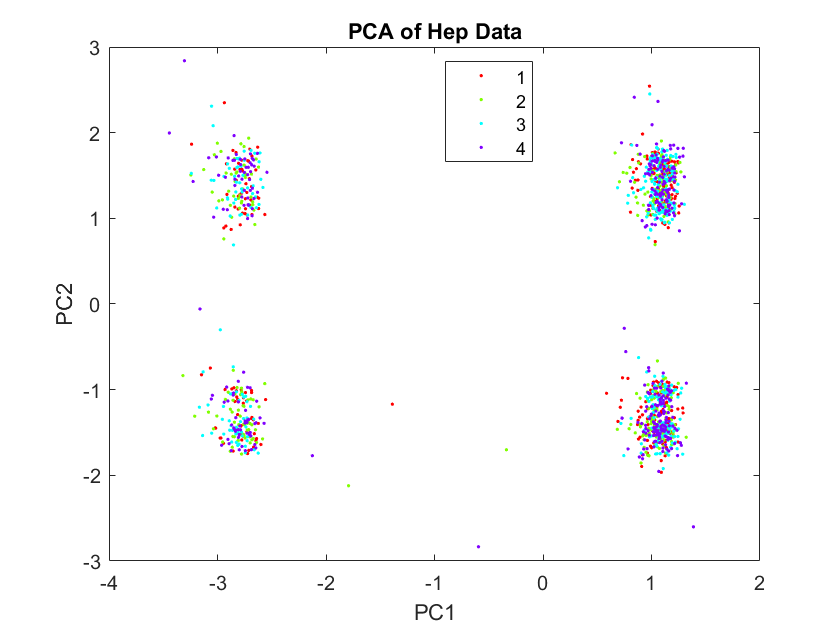

ans = 27×3 table
         features            PC1           PC2    
    __________________    _________    ___________

    {'RNAEOT'        }      0.57384    -0.00081004
    {'RNA12'         }      0.57292       0.001152
    {'RNAEF'         }      0.57289     -0.0032056
    {'Epigastricpain'}     0.041221      -0.027796
    {'ALT1'          }     0.040013      -0.024534
    {'Plat'          }     0.038251        0.03989
    {'Fever'         }     0.034347       0.022759
    {'ALT24'         }     0.033469     -0.0039955
    {'ALT48'         }     0.024784       0.039109
    {'ALT4'          }     0.022907      -0.080345
    {'Jaundice'      }     0.021958      0.0036026
    {'RNA4'          }     0.018943       0.023994
    {'AST1'          }     0.018834       0.012363
    {'Diarrhea'      }     0.012933    -0.00086872
    {'NauseaVomting' }    0.0074888      -0.043278
    {'ALTafte

ans = 27×3 table
               features                  PC1           PC2   
    ______________________________    __________    _________

    {'HGB'                       }      0.003318      0.69631
    {'Gender'                    }     0.0030055       0.6963
    {'Fatiguegeneralizedboneache'}     -0.008095      0.06718
    {'WBC'                       }     -0.014053     0.058621
    {'ALT36'                     }    -0.0051866     0.044819
    {'RBC'                       }     -0.041258     0.039917
    {'Plat'                      }      0.038251      0.03989
    {'ALT48'                     }      0.024784     0.039109
    {'RNABase'                   }     -0.012357     0.035265
    {'ALTafter24w'               }     0.0067853     0.033694
    {'RNA4'                      }      0.018943     0.023994
    {'Fever'                     }      0.034347     0.022759
    {'AST1' 

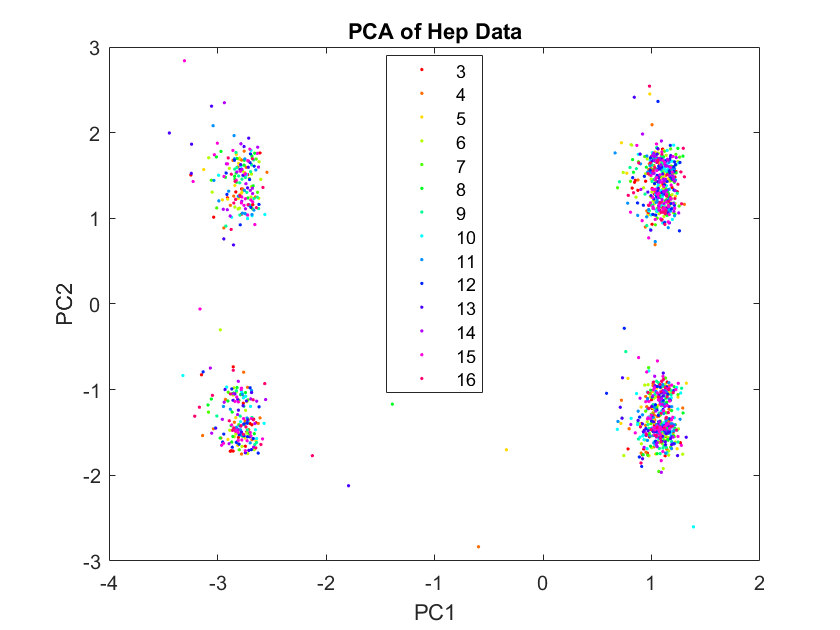

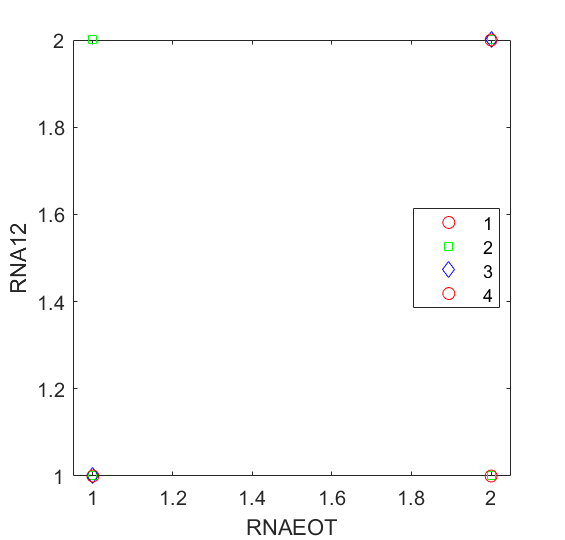

Unrecognized function or variable 'HCV1_array'.

disease_severity=HCV1.Baselinehistologicalstaging;

X=zscore(HCV_array(:,1:end-2));
[P,Y,~,~,explained]=pca(X);
figure
gscatter(Y(:,1),Y(:,2),disease_severity)
xlabel('PC1')
ylabel('PC2')
title('PCA of Hep Data')

mapcaplot(X', HCV.Properties.VariableNames(1:end-2))

This shows that 

- **PC1** differentiates RNAEOT, RNA12 and RNAEF from the rest of the variables (Lower-right corner)

- **PC2 **differentiates HGB and Gender from rest of the variables (Upper Left corner)

ans = 27×3 table
               features                 PC1          PC2   
    ______________________________    ________    _________

    {'RNA4'                      }     0.72582      -0.4678
    {'RNABase'                   }     0.20167      0.84517
    {'WBC'                       }    0.012385    0.0041804
    {'BMI'                       }    0.012077    0.0040608
    {'ALTafter24w'               }    0.012077    0.0040613
    {'ALT1'                      }    0.012077    0.0040638
    {'Age'                       }    0.012076    0.0040618
    {'Diarrhea'                  }    0.012076    0.0040611
    {'Fever'                     }    0.012076    0.0040611
    {'Gender'                    }    0.012076    0.0040611
    {'Headache'                  }    0.012076    0.0040612
    {'Jaundice'                  }    0.012076    0.0040611
    {'NauseaVomting'             }    0.

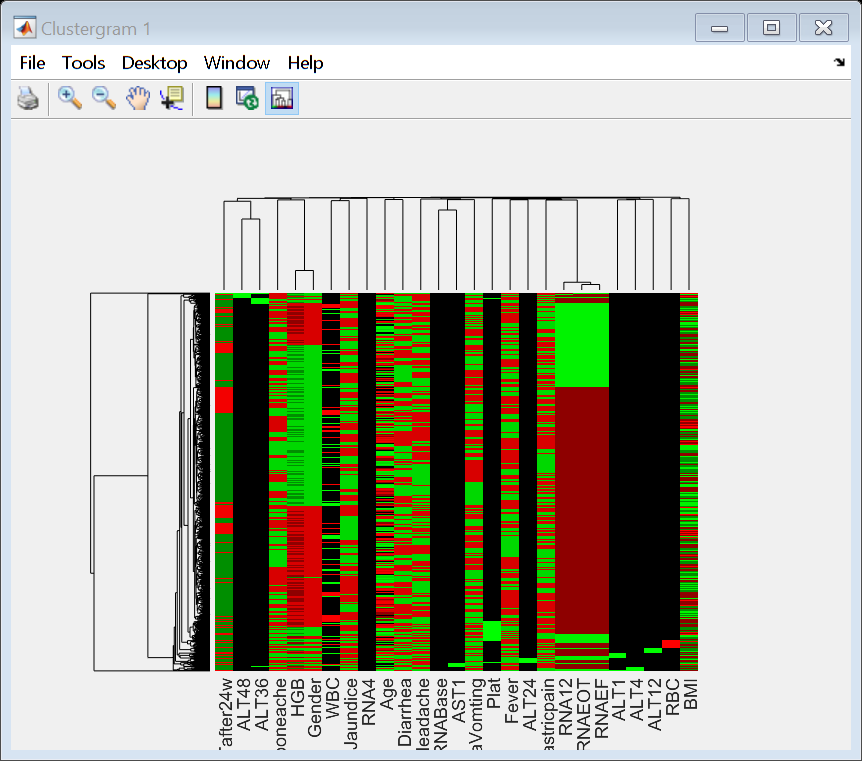

Clustergram object with 1385 rows of nodes and 27 columns of nodes.



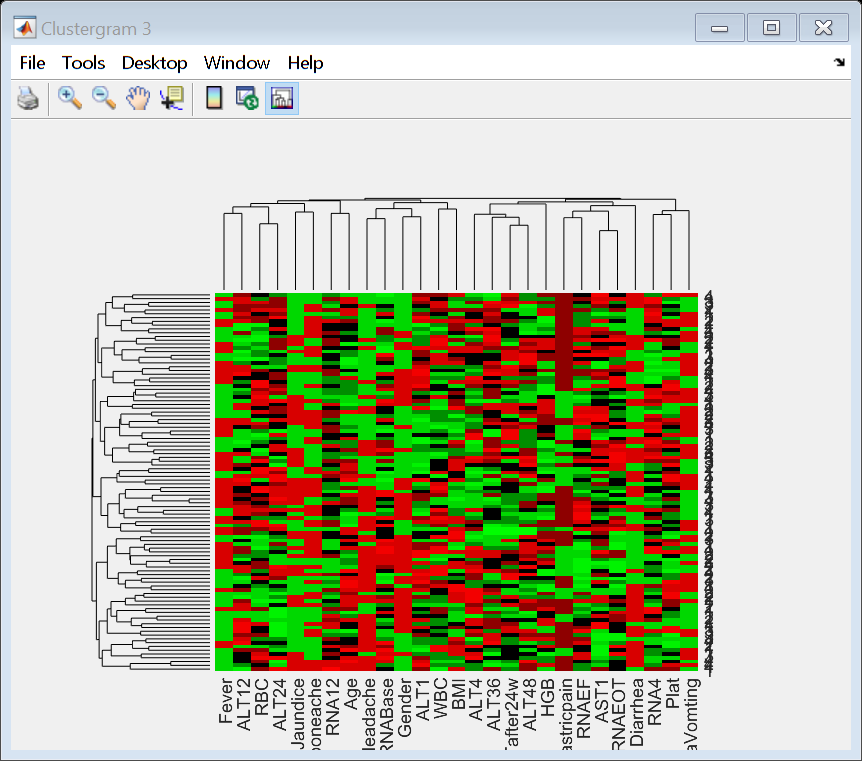

Clustergram object with 100 rows of nodes and 27 columns of nodes.



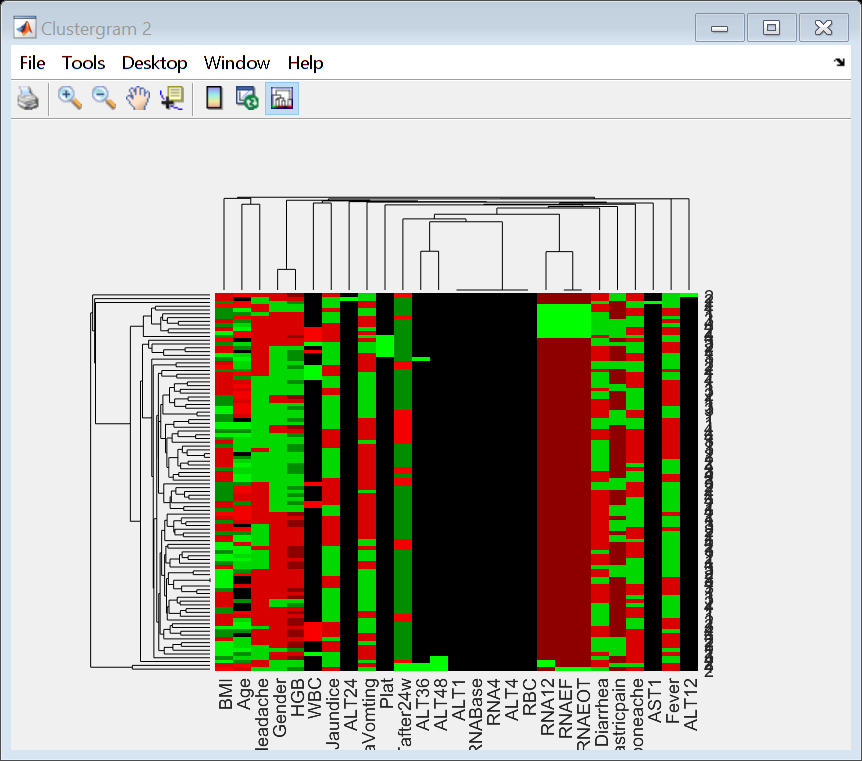

Clustergram object with 100 rows of nodes and 27 columns of nodes.



col_names=HCV1.Properties.VariableNames(1:end-2);

features=col_names';
PC1=P(:,1);
PC2=P(:,2);
f=table(features,PC1,PC2);
sortrows(f,'PC1','descend')

Decision_Tree =   ClassificationTree
           PredictorNames: {1×27 cell}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [1    2    3    4]
           ScoreTransform: 'none'
          NumObservations: 1385


  Properties, Methods


sortrows(f,'PC2','descend')


Decision tree for classification
  1  if HGB<1.5 then node 2 elseif HGB>=1.5 then node 3 else 4
  2  if Fever<1.5 then node 4 elseif Fever>=1.5 then node 5 else 2
  3  if ALT36<2.5 then node 6 elseif ALT36>=2.5 then node 7 else 3
  4  if RNAEOT<1.5 then node 8 elseif RNAEOT>=1.5 then node 9 else 4
  5  if Age<4.5 then node 10 elseif Age>=4.5 then node 11 else 2
  6  if ALT4<2.5 then node 12 elseif ALT4>=2.5 then node 13 else 2
  7  if NauseaVomting<1.5 then node 14 elseif NauseaVomting>=1.5 then node 15 else 3
  8  if Age<2.5 then node 16 elseif Age>=2.5 then node 17 else 3
  9  if Diarrhea<1.5 then node 18 elseif Diarrhea>=1.5 then node 19 else 4
 10  if Headache<1.5 then node 20 elseif Headache>=1.5 then node 21 else 1
 11  if Epigastricpain<1.5 then node 22 elseif Epigastricpain>=1.5 then node 23 else 3
 12  class = 3
 13  if Fever<1.5 then node 24 elseif Fever>=1.5 then node 25 else 2
 14  if WBC<2.5 then node 26 elseif WBC>=2.5 then node 27 else 1
 15  if Epigastricpain<1.5 then 

# PCA Grades

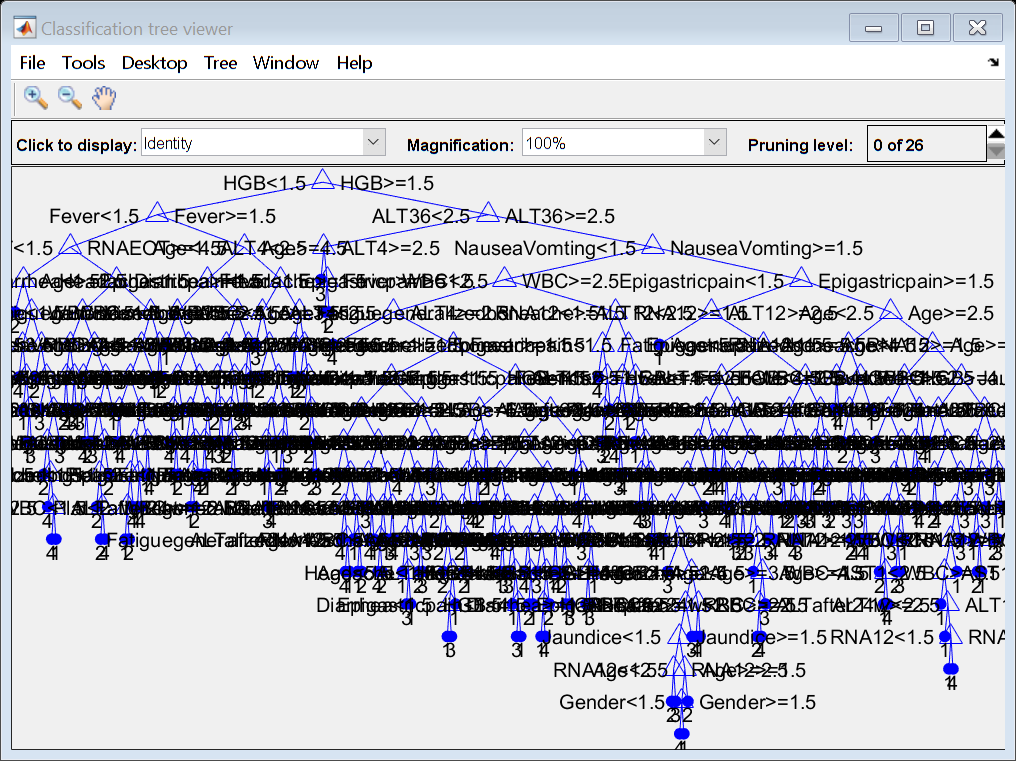

disease_severity=HCV1.BaselinehistologicalGrading;

X=zscore(HCV_array(:,1:end-2));
[P,Y,~,~,explained]=pca(X);
figure
gscatter(Y(:,1),Y(:,2),disease_severity)

Ypred = 416×1 categorical array
     4 
     1 
     4 
     3 
     3 
     4 
     3 
     1 
     1 
     4 
     2 
     3 
     1 
     4 
     2 
     1 
     4 
     2 
     3 
     2 
     3 
     4 
     1 
     4 
     4 
     2 
     2 
     3 
     2 
     4 


xlabel('PC1')

ans = 0.6034

ylabel('PC2')
title('PCA of Hep Data')

Decision_Tree =   ClassificationTree
           PredictorNames: {1×27 cell}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [1    2    3    4]
           ScoreTransform: 'none'
          NumObservations: 969


  Properties, Methods


mapcaplot(X', HCV.Properties.VariableNames(1:end-2))


Decision tree for classification
  1  if HGB<1.5 then node 2 elseif HGB>=1.5 then node 3 else 3
  2  if Age<2.5 then node 4 elseif Age>=2.5 then node 5 else 4
  3  if ALT36<2.5 then node 6 elseif ALT36>=2.5 then node 7 else 3
  4  if Diarrhea<1.5 then node 8 elseif Diarrhea>=1.5 then node 9 else 1
  5  if Jaundice<1.5 then node 10 elseif Jaundice>=1.5 then node 11 else 4
  6  class = 2
  7  if NauseaVomting<1.5 then node 12 elseif NauseaVomting>=1.5 then node 13 else 3
  8  if Plat<2 then node 14 elseif Plat>=2 then node 15 else 2
  9  if NauseaVomting<1.5 then node 16 elseif NauseaVomting>=1.5 then node 17 else 1
 10  if Age<4.5 then node 18 elseif Age>=4.5 then node 19 else 4
 11  if AST1<2.5 then node 20 elseif AST1>=2.5 then node 21 else 2
 12  if WBC<2.5 then node 22 elseif WBC>=2.5 then node 23 else 1
 13  if Epigastricpain<1.5 then node 24 elseif Epigastricpain>=1.5 then node 25 else 3
 14  class = 3
 15  if Fever<1.5 then node 26 elseif Fever>=1.5 then node 27 else 2
 16  clas

This shows similar results as above

- **PC1** differentiates RNAEOT, RNA12 and RNAEF from the rest of the variables (Lower-right corner)

- **PC2 **differentiates HGB and Gender from rest of the variables (Upper Left corner)

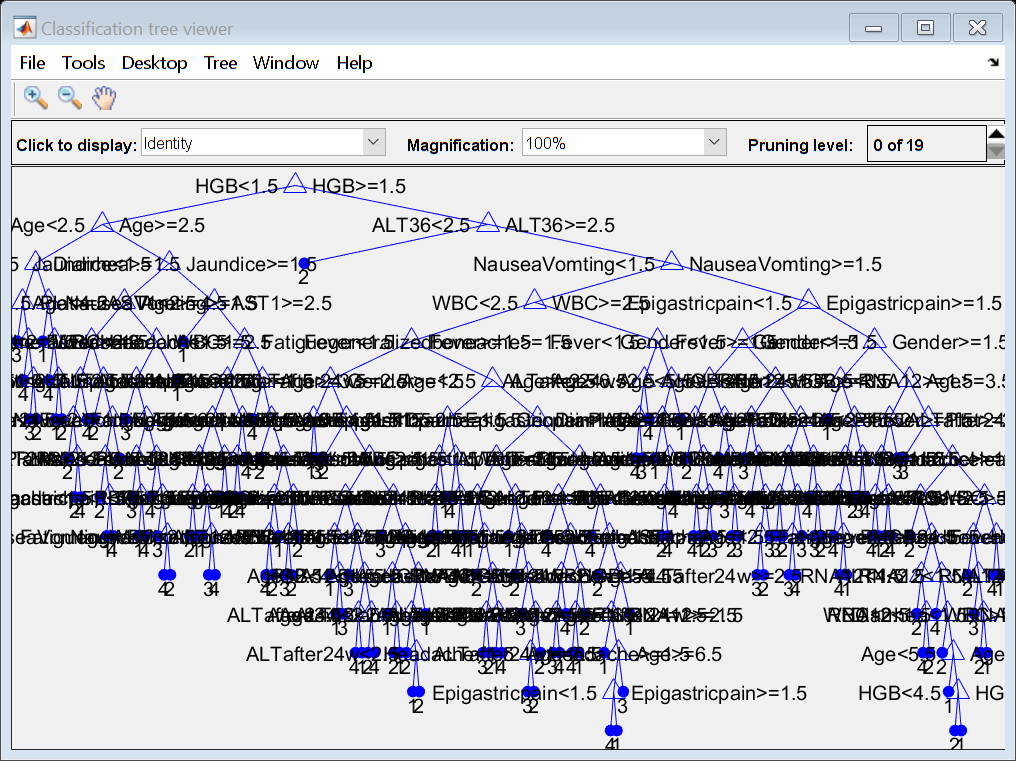

col_names=HCV1.Properties.VariableNames(1:end-2);

features=col_names';

Ypred = 416×1 categorical array
     2 
     3 
     3 
     3 
     1 
     3 
     4 
     3 
     4 
     1 
     2 
     4 
     3 
     3 
     2 
     3 
     2 
     4 
     2 
     2 
     4 
     2 
     3 
     2 
     1 
     3 
     2 
     2 
     4 
     3 


PC1=P(:,1);

ans = 0.2668

PC2=P(:,2);
f=table(features,PC1,PC2);
sortrows(f,'PC1','descend')

E =     0.7603
    0.7596
    0.7596
    0.7596
    0.7574
    0.7574
    0.7545
    0.7567
    0.7560
    0.7567


SE =     0.0114
    0.0114
    0.0114
    0.0114
    0.0114
    0.0114
    0.0115
    0.0115
    0.0115
    0.0115


Nleaf =    243
   233
   230
   226
   221
   138
   131
   122
   115
   107


Best_prune_level = 26

sortrows(f,'PC2','descend')

prune_tree =   ClassificationTree
           PredictorNames: {1×27 cell}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [1    2    3    4]
           ScoreTransform: 'none'
          NumObservations: 1385


  Properties, Methods


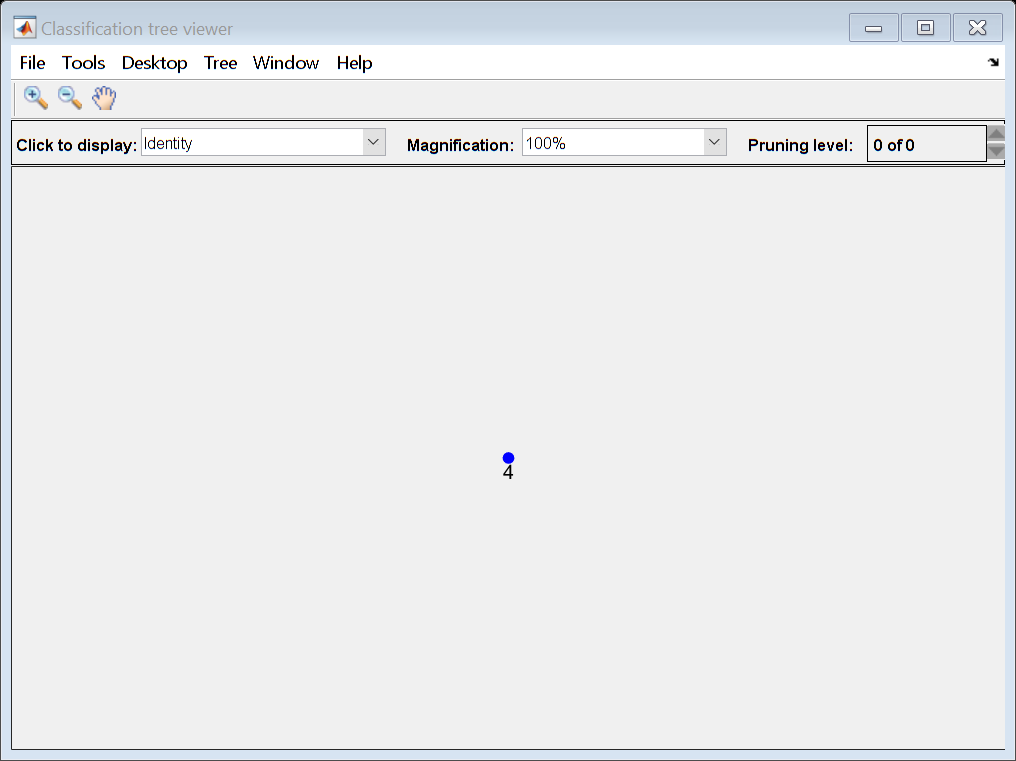

gscatter(HCV_array(:,26),HCV_array(:,25),disease_severity,'rgb','osd');

xlabel('RNAEOT');
ylabel('RNA12');

# PCA on whole numbers

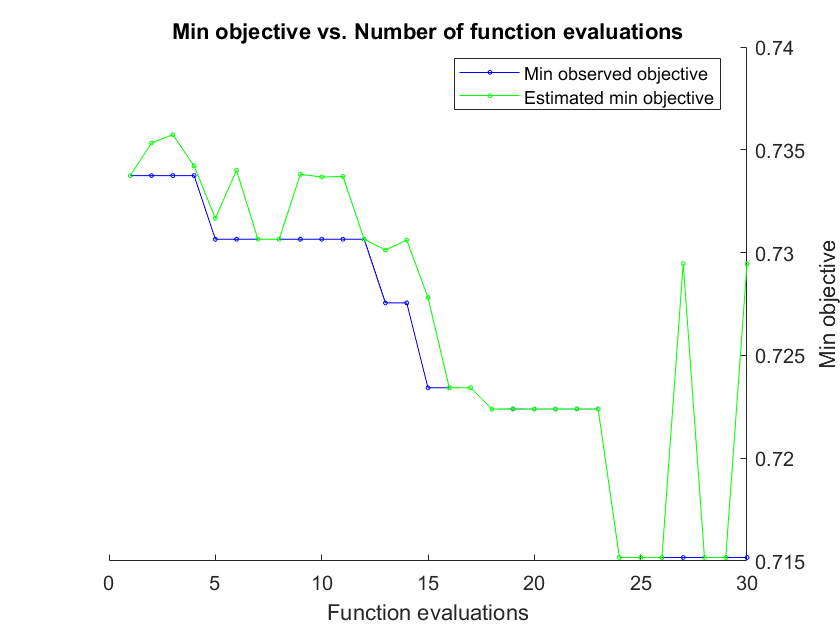

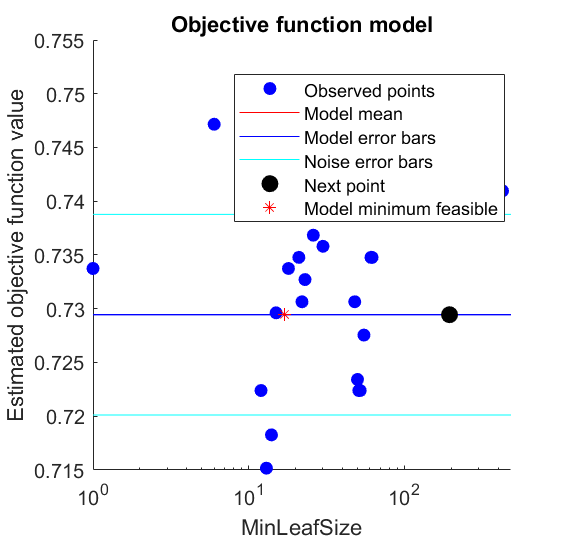

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |     0.73375 |     0.42399 |     0.73375 |     0.73375 |            1 |
|    2 | Accept |     0.74716 |     0.19835 |     0.73375 |     0.73533 |            6 |
|    3 | Accept |     0.73684 |     0.14681 |     0.73375 |     0.73574 |           26 |
|    4 | Accept |     0.74097 |     0.21859 |     0.73375 |     0.73422 |          427 |
|    5 | Best   |     0.73065 |     0.16095 |     0.73065 |     0.73168 |           22 |
|    6 | Accept |     0.73478 |     0.21334 |     0.73065 |       0.734 |           21 |
|    7 | Accept |     0.73478 |     0.10672 |     0.73065 |     0.73065 |           21 |
|    8 | Accept |    

Mdl1 =   ClassificationTree
                       PredictorNames: {1×27 cell}
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [1    2    3    4]
                       ScoreTransform: 'none'
                      NumObservations: 969
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]


  Properties, Methods


disease_severity=HCV.Baselinehistologicalstaging;

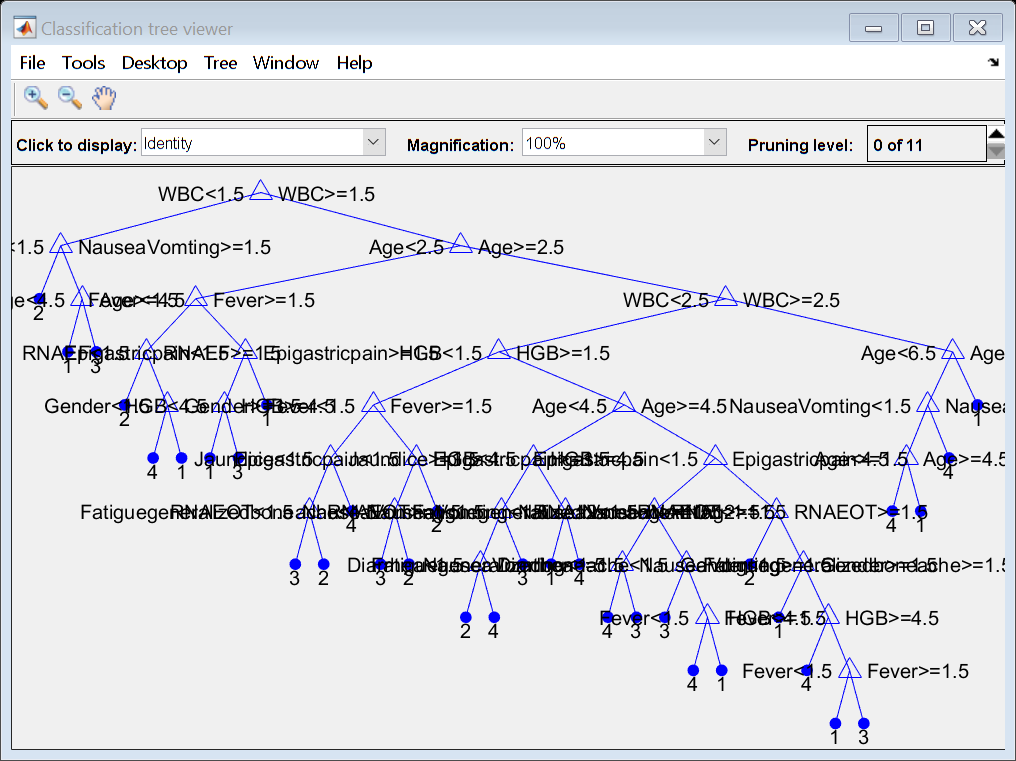

X=normalize(HCV1_array(:,1:end-2),2)

[P,Y,~,~,explained]=pca(X);
figure

Bestobsmdl =   ClassificationTree
           PredictorNames: {1×27 cell}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [1    2    3    4]
           ScoreTransform: 'none'
          NumObservations: 969


  Properties, Methods


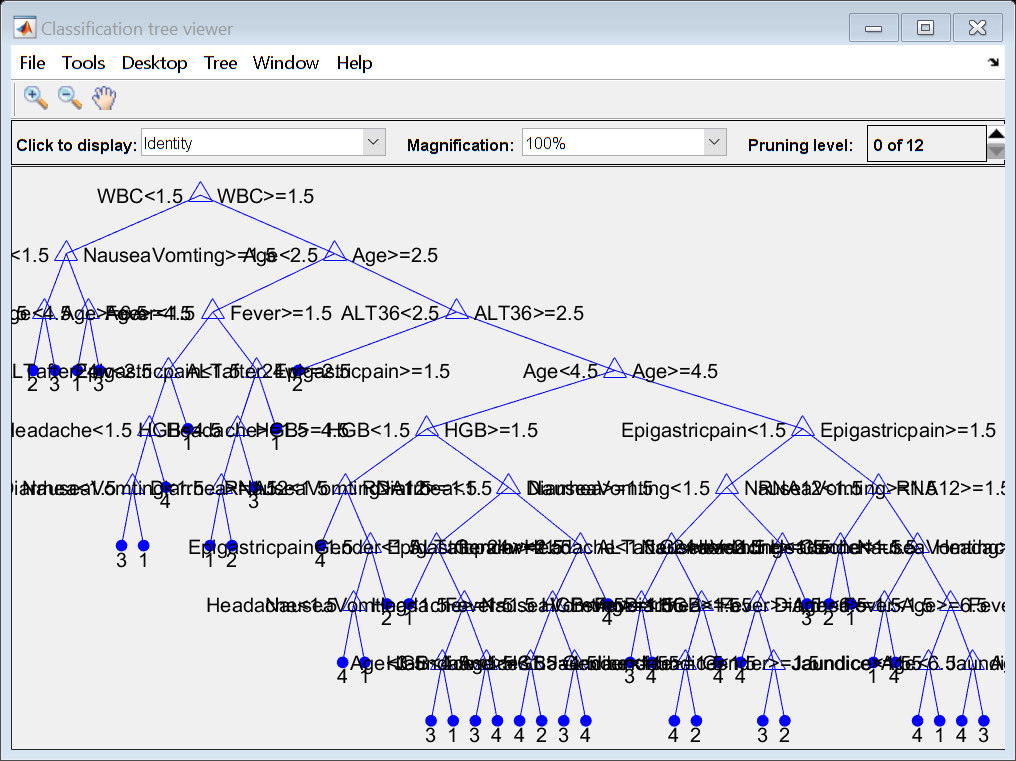

gscatter(Y(:,1),Y(:,2),disease_severity)

xlabel('PC1')
ylabel('PC2')

Bestestmdl =   ClassificationTree
           PredictorNames: {1×27 cell}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [1    2    3    4]
           ScoreTransform: 'none'
          NumObservations: 969


  Properties, Methods


title('PCA of Hep Data')

mapcaplot(X', HCV.Properties.VariableNames(1:end-2))

Ypred = 416×1 categorical array
     2 
     1 
     2 
     3 
     2 
     1 
     3 
     3 
     2 
     3 
     1 
     4 
     3 
     1 
     2 
     4 
     1 
     4 
     1 
     1 
     4 
     2 
     1 
     4 
     4 
     4 
     1 
     1 
     4 
     1 


This shows that 

- **PC1** differentiates RNAEOT, RNA12 and RNAEF from the rest of the variables (Lower-right corner)

col_names=HCV1.Properties.VariableNames(1:end-2);

ans = 0.3822

features=col_names';
PC1=P(:,1);
PC2=P(:,2);

HCV1_array =           56           1          35           2           1           1           1           2           2           2        7425     4248807          14      112132          99          84          52         109          81           5           5           5      655330      634536      288194           5           5          13           2
          46           1          29           1           2           2           1           2           2           1       12101     4429425          10      129367          91         123          95          75         113          57         123          44       40620      538635      637056      336804       31085           4           2
          57           1          33           2           2           2           2           1           1           1        4178     4621191          12      151522         113          49          95         107         116           5           5           5      571148      661346 

f=table(features,PC1,PC2);
sortrows(f,'PC1','descend')

# Decision Tree

X=HCV1(:,1:end-2); % no stages

b =    -0.0445    0.6575    0.0199
    0.0510   -0.1120    0.2766
   -0.0062   -0.0332   -0.0408
   -0.0000   -0.0000    0.0000


Y=categorical(HCV1.Baselinehistologicalstaging);

Ypred =     0.2448    0.2878    0.2019    0.2655
    0.2323    0.2996    0.2217    0.2464
    0.2440    0.2301    0.2511    0.2748
    0.2334    0.1950    0.3245    0.2471
    0.2383    0.2696    0.2329    0.2592
    0.2495    0.2426    0.2491    0.2588
    0.2401    0.1852    0.3161    0.2587
    0.2371    0.2002    0.3119    0.2509
    0.2411    0.2708    0.2251    0.2630
    0.2440    0.2304    0.2508    0.2747


Decision_Tree=fitctree(X,Y)
view(Decision_Tree)

r = 1385

view(Decision_Tree,'mode','graph')

[Xtrain,Ytrain,Xtest,Ytest]=trainTestSplit(X,Y,0.7);

Ypred=predict(Decision_Tree,Xtest); 

ans =      2     2
     2     2
     4     4
     3     3
     2     1
     4     4
     3     4
     3     3
     2     2
     4     2


sum(Ypred==Ytest)/length(Ytest)

Ypred =     0.2448    0.2878    0.2019    0.2655
    0.2323    0.2996    0.2217    0.2464
    0.2440    0.2301    0.2511    0.2748
    0.2334    0.1950    0.3245    0.2471
    0.2383    0.2696    0.2329    0.2592
    0.2495    0.2426    0.2491    0.2588
    0.2401    0.1852    0.3161    0.2587
    0.2371    0.2002    0.3119    0.2509
    0.2411    0.2708    0.2251    0.2630
    0.2440    0.2304    0.2508    0.2747


Decision_Tree=fitctree(Xtrain,Ytrain)

ans = 0.2989

view(Decision_Tree)
view(Decision_Tree,'mode','graph')
Ypred=predict(Decision_Tree,Xtest); 
sum(Ypred==Ytest)/length(Ytest)

## Pruning a tree

[E,SE,Nleaf,Best_prune_level]=cvloss(Decision_Tree,'subtrees','all')

Ypred =     0.2418    0.2937    0.1928    0.2717
    0.2458    0.2095    0.2951    0.2496
    0.2618    0.2578    0.2032    0.2772
    0.2433    0.1687    0.3181    0.2698
    0.2497    0.1796    0.3022    0.2684
    0.2464    0.2992    0.2286    0.2257
    0.2669    0.2232    0.2402    0.2696
    0.2580    0.2859    0.1780    0.2780
    0.2388    0.1494    0.3940    0.2178
    0.2626    0.2745    0.2055    0.2574


prune_tree=prune(Decision_Tree,'Level',Best_prune_level)

r = 416

view(prune_tree,'mode','graph') % Best cross validation accuracy

## Finding best Hyperparameters

Mdl1=fitctree(Xtrain,Ytrain,'OptimizeHyperparameters','auto')
view(Mdl1,'mode','graph')

Bestobsmdl=fitctree(Xtrain,Ytrain,'MinLeafsize',13)

Ypred =     0.2418    0.2937    0.1928    0.2717
    0.2458    0.2095    0.2951    0.2496
    0.2618    0.2578    0.2032    0.2772
    0.2433    0.1687    0.3181    0.2698
    0.2497    0.1796    0.3022    0.2684
    0.2464    0.2992    0.2286    0.2257
    0.2669    0.2232    0.2402    0.2696
    0.2580    0.2859    0.1780    0.2780
    0.2388    0.1494    0.3940    0.2178
    0.2626    0.2745    0.2055    0.2574


view(Bestobsmdl,'mode','graph')

ans =      2     2
     3     2
     4     2
     3     1
     3     2
     2     1
     4     3
     2     4
     3     3
     2     1


Bestestmdl=fitctree(Xtrain,Ytrain,'MinLeafsize',18)

ans = 0.2620

view(Bestestmdl,'mode','graph')

Ypred=predict(Bestestmdl,Xtest) 
sum(Ypred==Ytest)/length(Ytest)

# Logistic Regression

HCV1_array=table2array(HCV)
h=HCV1_array(:,[2,13,27]);
Stage=HCV1_array(:,end);

b=mnrfit(h,categorical(Stage))

ans = 26×2 table
    Var1    s_score
    ____    _______

      2     0.35759
      3     0.37039
      4     0.41817
      5     0.34108
      6     0.26263
      7     0.25531
      8     0.22431
      9     0.24334
     10     0.23424
     11     0.19391
     12     0.20213
     13     0.17945
     14      0.2262
     15     0.19854
     16     0.19892
     17     0.19165


Ypred=mnrval(b,h)

k = 4

r=length(Ypred)

The optimal number of patient groups with k-means clustering using silhouette analysis is 4

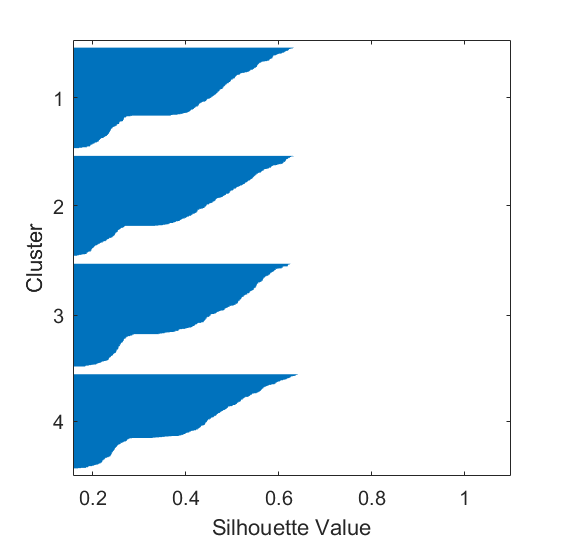

prediction_1=zeros(r,1);
for j=1:r

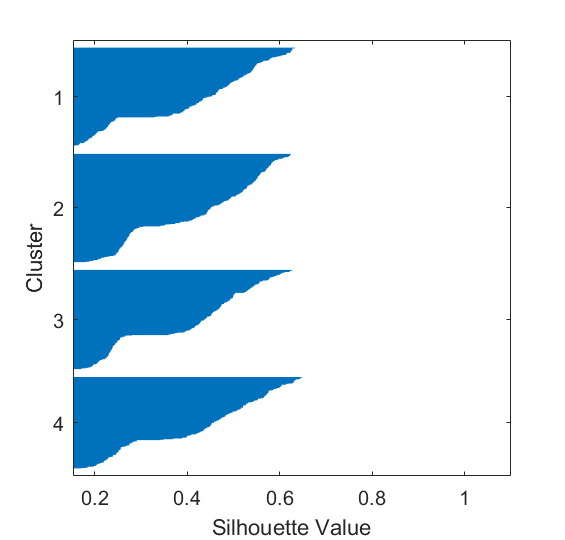

    [k, idk]=maxk(Ypred(j,:),1);
    prediction_1(j)=idk;
end
[prediction_1 Stage]

Ypred
sum(prediction_1==Stage)/1385

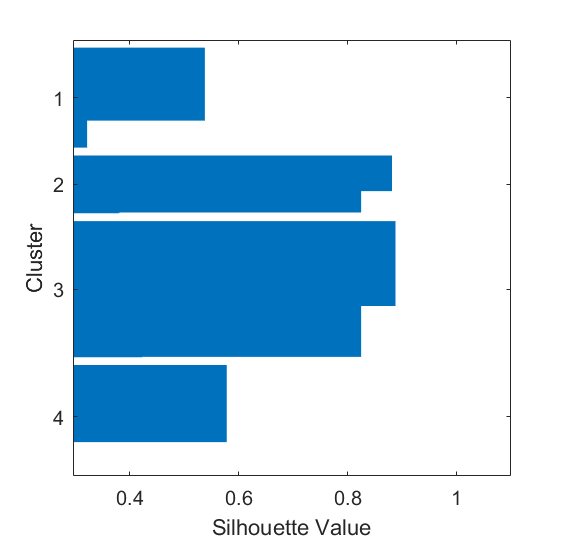

ratio=0.70;
[Xtrain1, Ytrain1, Xtest1, Ytest1]=trainTestSplit(h,Stage,ratio);

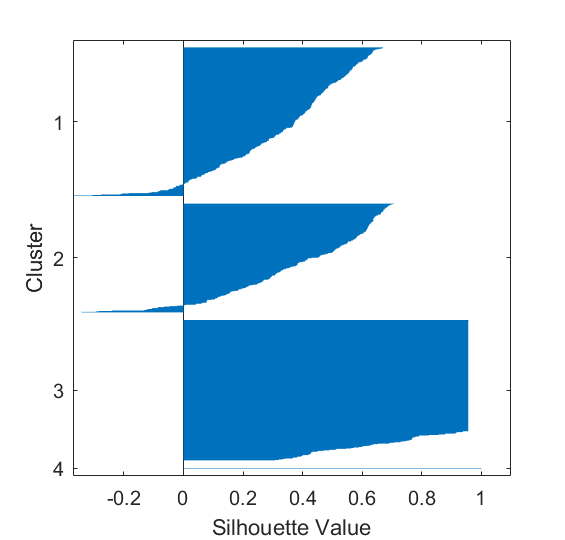

[b,dev,stats] = mnrfit(Xtrain1, categorical(Ytrain1)); 
Ypred = mnrval(b,Xtest1)
r=length(Ypred)
prediction_1=zeros(r,1);

for j=1:r
    [k, idk]=maxk(Ypred(j,:),1);
    prediction_1(j)=idk;
end
Ypred
[prediction_1 Ytest1]
sum(prediction_1==Ytest1)/r

# K-means Clustering - yayieeeeee

k_values=2:27; % Exclude histological values -staging
n=length(k_values);
s_score=zeros(n,1);
for i=1:n
    idx=kmeans(HCV_array(:,1:end-2),k_values(i));
    s=silhouette(HCV_array(:,1:end-2),idx);
    s_score(i)=mean(s);
end
table(k_values',s_score)
k=find(s_score==max(s_score))+1
fprintf('The optimal number of patient groups with k-means clustering using silhouette analysis is %d',k)
idx=kmeans(HCV_array(:,1:end-2),k);
silhouette(HCV_array(:,1:end-2),idx)

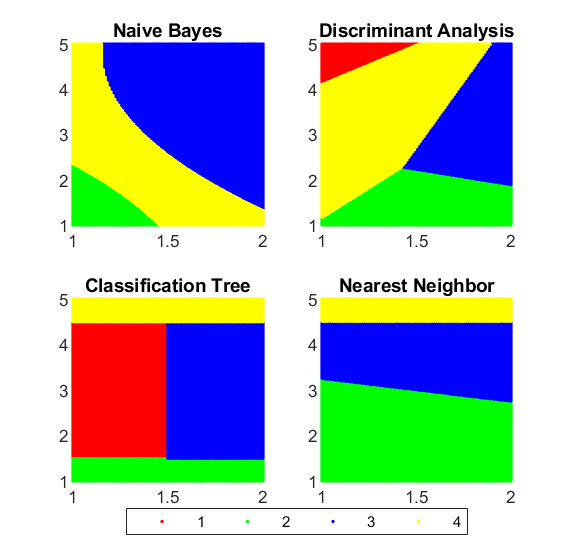

[Xtrain,Ytrain,Xtest,Ytest]=trainTestSplit(HCV_array(:,1:end-2),categorical(HCV_array(:,end)),0.7);

idx=kmeans(Xtrain,4);
silhouette(Xtrain,idx)

[Xtrain,Ytrain,Xtest,Ytest]=trainTestSplit(HCV_array(:,[2,13,25:27]),categorical(HCV_array(:,end)),0.7);
idx=kmeans(Xtrain,4);
silhouette(Xtrain,idx)

[Xtrain,Ytrain,Xtest,Ytest]=trainTestSplit(HCV1_array(:,[2,13,25:27]),categorical(HCV1_array(:,end)),0.6);
idx=kmeans(Xtrain,4);
silhouette(Xtrain,idx)

# Different classification techniques

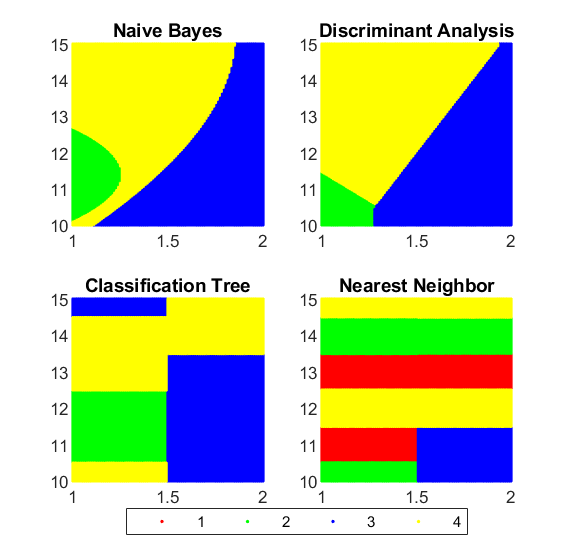

% Discrete data 
X=HCV_array(:,[2,13]);
y=categorical(HCV_array(:,29));
labels = categories(y);

classifier_name = {'Naive Bayes','Discriminant Analysis','Classification Tree','Nearest Neighbor'};
classifier{1} = fitcnb(X,y);
classifier{2} = fitcdiscr(X,y); % Discriminant analysis of prinicipal components
classifier{3} = fitctree(X,y);
classifier{4} = fitcknn(X,y);

x1range = min(X(:,1)):.01:max(X(:,1));
x2range = min(X(:,2)):.01:max(X(:,2));
[xx1, xx2] = meshgrid(x1range,x2range);
XGrid = [xx1(:) xx2(:)];

for i = 1:numel(classifier)
   predictedspecies = predict(classifier{i},XGrid);


   subplot(2,2,i);
   gscatter(xx1(:), xx2(:), predictedspecies,'rgby');

   title(classifier_name{i})
   legend off, axis tight
end

x1 = 	1.0e+07 *

   -0.0000   -0.0000   -0.0000
    0.0000    0.0000    0.0000
   -1.0393    0.3336    0.7519
    0.6055    0.0692    0.5200
    0.1426   -0.8075    0.5118
    0.5161   -0.0530    0.7628


B4_PLS =     2.5633
    0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
    0.0000


PctVar =     0.3534    0.1572    0.3425
    0.0031    0.0011    0.0000



legend(labels,'Location',[0.35,0.01,0.35,0.05],'Orientation','Horizontal')

% Real data - works only on small values
X=HCV1_array(:,[2,13]);

PLS_mse = 	1.0e+11 *

    3.5472    2.3554    1.7142    0.5739    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


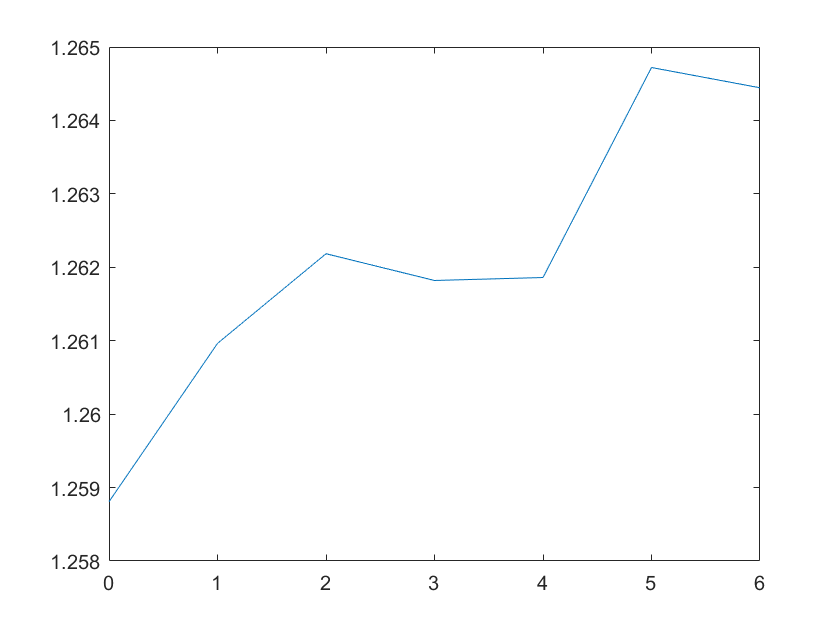

y=categorical(HCV1_array(:,29));
labels = categories(y);


classifier_name = {'Naive Bayes','Discriminant Analysis','Classification Tree','Nearest Neighbor'};
classifier{1} = fitcnb(X,y);
classifier{2} = fitcdiscr(X,y); 
classifier{3} = fitctree(X,y);
classifier{4} = fitcknn(X,y);

x1range = min(X(:,1)):.01:max(X(:,1));

x2range = min(X(:,2)):.01:max(X(:,2));
[xx1, xx2] = meshgrid(x1range,x2range);
XGrid = [xx1(:) xx2(:)];

for i = 1:numel(classifier)
   predictedspecies = predict(classifier{i},XGrid);


   subplot(2,2,i);
   gscatter(xx1(:), xx2(:), predictedspecies,'rgby');

ans =     1.0196    1.0138    1.0000    1.0000   52.6308   52.6308
    0.9880    0.9880    0.7682    0.7682       NaN       NaN
    1.0573    1.0686    1.0000    1.0000   52.6308   52.6308
    1.0310    1.0310    0.7625    0.7625       NaN       NaN
    0.9451    0.9451    0.7552    0.7552       NaN       NaN
    1.0020    1.0020    0.7617    0.7617       NaN       NaN
    1.0056    1.0056    0.7697    0.7697       NaN       NaN
    0.9854    0.9854    0.7487    0.7487       NaN       NaN
    0.9798    0.9798    0.7422    0.7422       NaN       NaN
    1.0521    1.0521    0.7755    0.7755       NaN       NaN



   title(classifier_name{i})
   legend off, axis tight
end

legend(labels,'Location',[0.35,0.01,0.35,0.05],'Orientation','Horizontal')


%PLS Regression
x=HCV1_array(:,[2,13,24:27]);
y=HCV1_array(:,end);
[x1,~,~,~,B4_PLS,PctVar]=plsregress(x,y,3) %x1->loadings for regression, 

% x1 is a function of all the columns represented in 3 variables as factors eg: 1st=5*1st column
% B4_PLS are the regression coefficients
% PCtVar 1st row x 2nd row y of the 3 variables considered. % of data explaining the relationship


ans =     1.0196    1.0138    1.0000    1.0000   52.6308   52.6308
         0         0         0         0         0         0
    1.0573    1.0686    1.0000    1.0000   52.6308   52.6308
         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0


% Find the best number of groups using CV
[~,~,~,~,~,~,PLS_mse]=plsregress(x,y,6,'cv',5) % Gives cross validation error -> MSE of 6 


ans =     1.1024   -0.9789    1.5680    0.9691   -1.0047   -0.9917   -1.0047    1.0018    0.9975    0.9917   -0.0406   -0.5004    0.8242   -1.1913    0.6242    0.0032   -1.1838    0.9779   -0.1034   -2.9591   -2.9984   -4.0204    0.1819    0.0928   -0.0020   -1.0873   -1.0884
   -0.0363   -0.9789    0.0960   -1.0312    0.9946    1.0076   -1.0047    1.0018    0.9975   -1.0076    1.7119    0.0211   -1.5102   -0.7470    0.3164    1.5077    0.4370   -0.3265    1.1177   -0.9893    1.5013    1.4931   -1.5549   -0.1718    1.2206    0.1858   -0.9723
    1.2163   -0.9789    1.0773    0.9691    0.9946    1.0076    0.9946   -0.9975   -1.0018   -1.0076   -1.2575    0.5747   -0.3430   -0.1760    1.1628   -1.3469    0.4370    0.9012    1.2322   -2.9591   -2.9984   -4.0204   -0.0560    0.1668   -1.0119    1.6945    0.9991
    0.3053    1.0208    1.0773   -1.0312    0.9946   -0.9917    0.9946   -0.9975    0.9975   -1.0076   -0.3910    1.0755   -1.5102   -0.3065   -1.5302   -0.7683    0.9647   -0.1347 

% The range is big in case of 1 and 2 and less in 6,7

ans =     0.8849   -0.9789    1.9172    0.9691   -1.0047   -0.9917   -1.0047    1.0018    0.9975    0.9917   -0.0341   -0.1436   -0.5450    0.2442    0.1081    0.1210    0.1046    0.1270    0.1081  -12.3786  -14.2951   -2.8522    0.0269    0.0269    0.6203   -1.6140   -1.6198
   -0.2708   -0.9789   -0.3293   -1.0312    0.9946    1.0076   -1.0047    1.0018    0.9975   -1.0076    2.0181   -0.1436   -1.1488    0.2442    0.1081    0.1210    0.1046    0.1270    0.1081    0.1355    0.1092    1.7093    0.0269    0.0269    0.6203    0.6191    0.6169
    1.4628   -0.9789    0.7940    0.9691    0.9946    1.0076    0.9946   -0.9975   -1.0018   -1.0076   -0.0341   -0.1436   -1.1488    0.2442    0.1081    0.1210    0.1046    0.1270    0.1081  -12.3786  -14.2951   -2.8522    0.0269    0.0269   -1.6111    0.6191    0.6169
    0.3071    1.0208    0.7940   -1.0312    0.9946   -0.9917    0.9946   -0.9975    0.9975   -1.0076   -0.0341   -0.1436    0.6627    0.2442    0.1081    0.1210    0.1046    0.1270 

plot(0:6,PLS_mse(2,:))

func_corr=zeros(27,3);

ans = -0.0196

for i=1:27
    func_corr(i,1)=pdist([HCV.(i)';HCV.Baselinehistologicalstaging'],'correlation');

funccorr =     1.2563    2.3202    2.4653   12.1045    1.6058    2.6167    3.0077    1.3077    2.3569    2.1492    3.4357    1.0452    3.1792    1.4731    1.2449    1.0381    1.5848    1.8690    2.7960    1.7522    1.0242    1.2063    3.0898    3.1257    1.0427    2.1216    1.8349    1.5963    2.3111    1.5200    1.5215    2.6082    1.5014    1.7979    3.2309    1.2969    1.8191    1.8022    2.1505    2.5660    1.4326    1.6222    2.9835    1.5834    1.8682    2.4385    1.9351    2.4634    2.0157    2.1244


    func_corr(i,2)=pdist([HCV.(i)';HCV.Baselinehistologicalstaging'],'hamming');
    func_corr(i,3)=pdist([HCV.(i)';HCV.Baselinehistologicalstaging'],'seuclidean');

X =       634536           5
      538635       31085
      661346      558829
      449939      582301
      738756      242861
     1086852           5
     1034008      635157
       72050      506296
      757361      203042
      230488      555516


end

z = 	1.0e+07 *

    0.0000    0.0000    0.0000
    0.0001    0.0001    0.0000
    0.0001    0.0001    0.0000
    0.0001    0.0001    0.0000
    0.0000    0.0001    0.0000
    0.0001    0.0001    0.0000
    0.0001    0.0001    0.0000
    0.0001    0.0001    0.0000
    0.0001    0.0001    0.0000
    0.0000    0.0001    0.0000


T =      4
     4
     1
     2
     4
     4
     1
     3
     4
     2


func_corr_disc=zeros(27,3);

ans = 0.2332

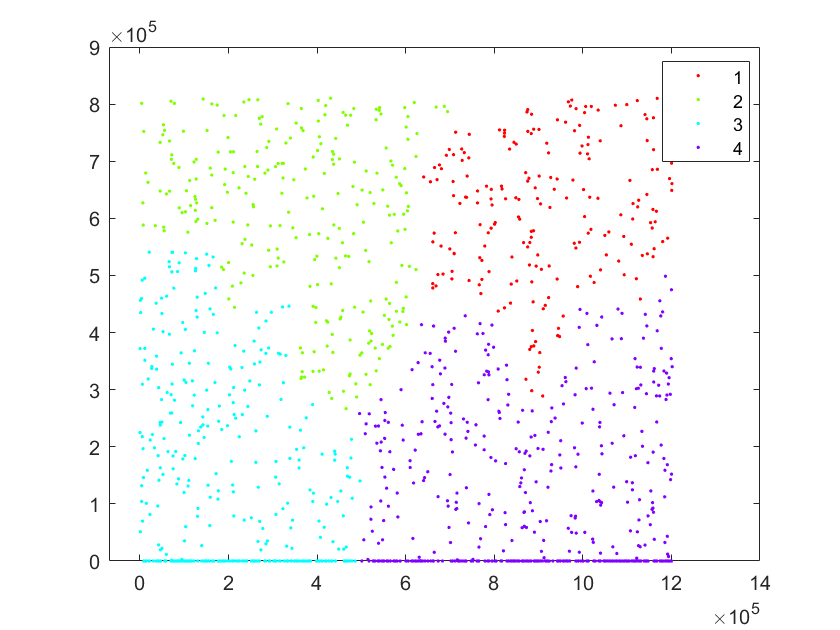

for i=1:27

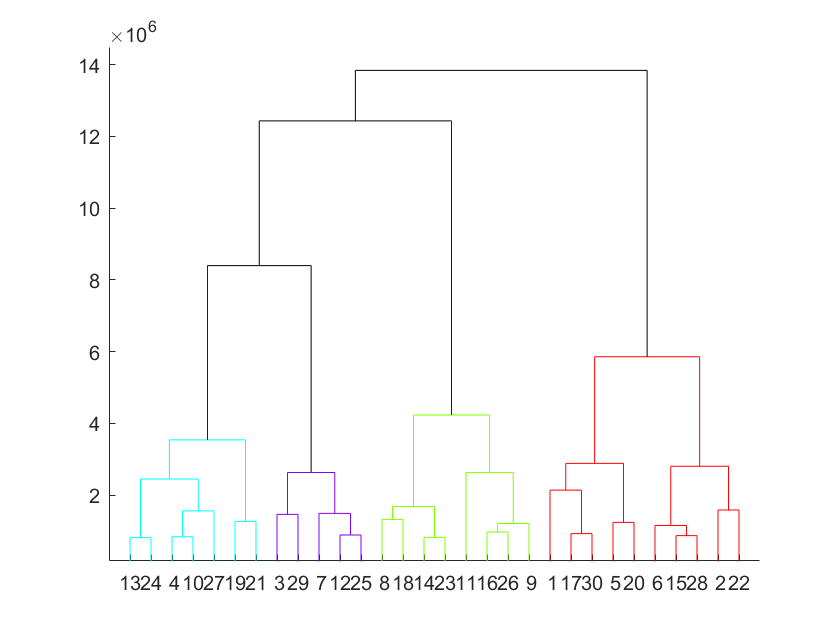

    func_corr_disc(i,1)=pdist([HCV1.(i)';HCV1.Baselinehistologicalstaging'],'correlation');
    func_corr_disc(i,2)=pdist([HCV.(i)';HCV.Baselinehistologicalstaging'],'hamming');

    func_corr_disc(i,3)=pdist([HCV.(i)';HCV.Baselinehistologicalstaging'],'seuclidean');

lastThree =         2761        2764
        2765        2767
        2766        2768


end

[func_corr(:,1) func_corr_disc(:,1) func_corr(:,2) func_corr_disc(:,2) func_corr(:,3) func_corr_disc(:,3)]

square euclidean not good with categorical data

Hamming doesn't go beyond 1 for non-categorical data

Only non-categorical data

func_corr=zeros(27,3);

Error using linsolve
Matrix must be positive definite.

Error in mnrfit (line 252)
            bcov = linsolve(hess,eye(size(hess)),struct('SYM',true,'POSDEF',true));

for i=[1,3,11:27]
    func_corr(i,1)=pdist([HCV.(i)';HCV.Baselinehistologicalstaging'],'correlation');
    func_corr(i,2)=pdist([HCV.(i)';HCV.Baselinehistologicalstaging'],'hamming');
    func_corr(i,3)=pdist([HCV.(i)';HCV.Baselinehistologicalstaging'],'seuclidean');

X =      5     2     2     4     3     3     3     3     3     3     3     3     2     3     2     2     2     2
     5     2     2     4     3     3     3     3     3     3     3     3     2     3     2     2     2     2
     3     2     2     4     3     3     3     3     3     3     3     3     2     3     2     2     2     2
     2     2     2     2     3     3     3     3     3     3     3     3     2     3     2     2     2     2
     7     2     2     1     3     3     3     3     3     3     3     3     2     3     2     2     2     2
     6     2     2     5     3     3     3     3     3     3     3     3     2     3     2     2     2     2
     6     2     2     2     3     3     3     3     3     3     3     3     2     3     2     2     2     2
     7     2     2     5     3     3     3     3     3     3     3     3     2     3     2     2     2     2
     3     2     2     4     3     3     3     3     3     3     3     3     2     3     2     2     2     2
     5     2   

end

z =    428   431     0
   433   457     0
   429   438     0
   439   470     0
   476   493     0
   453   482     0
   399   495     0
   483   490     0
     3   497     0
   421   449     0


T =      4
     4
     3
     2
     1
     4
     1
     4
     3
     4


func_corr_disc=zeros(27,3);

accuracy = 0.2692

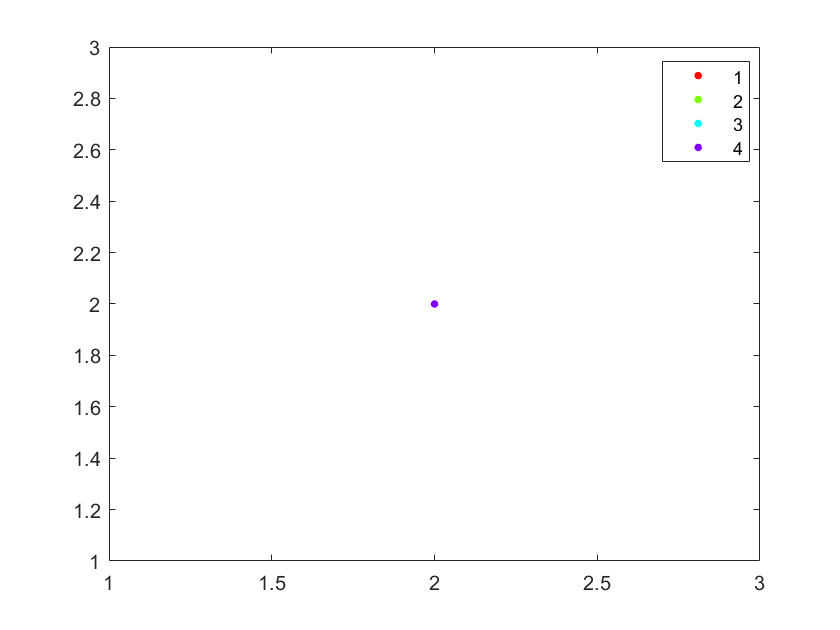

for i=[1,3,11:27]

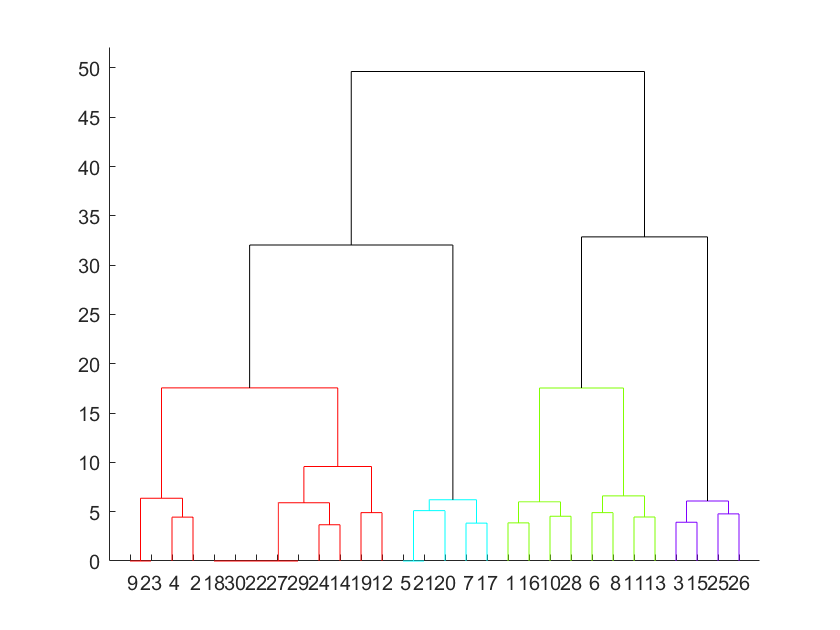

    func_corr_disc(i,1)=pdist([HCV1.(i)';HCV1.Baselinehistologicalstaging'],'correlation');
    func_corr_disc(i,2)=pdist([HCV.(i)';HCV.Baselinehistologicalstaging'],'hamming');

    func_corr_disc(i,3)=pdist([HCV.(i)';HCV.Baselinehistologicalstaging'],'seuclidean');

lastThree =    979   984
   978   983
   985   986


end


dat =     0.8276         0    1.0000    1.0000         0         0         0    1.0000    1.0000    1.0000    0.4867    0.3597    0.8000    0.1433    0.6742    0.5056    0.1461    0.7865    0.4719         0         0         0    0.5456    0.5280    0.0772         0         0
    0.4828         0    0.5385         0    1.0000    1.0000         0    1.0000    1.0000         0    1.0000    0.5100         0    0.2724    0.5843    0.9438    0.6292    0.4045    0.8315    0.4228    0.9593    0.9750    0.0338    0.4482    0.1707    0.4166    0.0384
    0.8621         0    0.8462    1.0000    1.0000    1.0000    1.0000         0         0         0    0.1303    0.6695    0.4000    0.4384    0.8315    0.1124    0.6292    0.7640    0.8652         0         0         0    0.4755    0.5503         0    0.9103    0.6896
    0.5862    1.0000    0.8462         0    1.0000         0    1.0000         0    1.0000         0    0.3841    0.8138         0    0.4005    0.0449    0.2809    0.7865    0.4607 

[func_corr(:,1) func_corr_disc(:,1) func_corr(:,2) func_corr_disc(:,2) func_corr(:,3) func_corr_disc(:,3)]

Argument to dynamic structure reference must evaluate to a valid field name.

Doesn't make a difference

zscore(HCV1_array(:,1:27)) %goes to -4
zscore(HCV_array(:,1:27))% goes to -14

corr(HCV1_array(:,1),HCV1_array(:,29))

v =      1     2     3     4     5


funccorr=pdist([HCV.(24), HCV.(25),HCV.(27)],'seuclidean')

ans =     0.0667    0.1333    0.2000    0.2667    0.3333


X=[HCV.(24), HCV.(27)]

ans =     0.0009    0.0007
    0.0007    0.0016
    0.0009    0.0000
    0.0008    0.0015
    0.0009    0.0093
    0.0009    0.0000
    0.0007    0.0007
    0.0007    0.0020
    0.0007    0.0000
    0.0007    0.0007


z=linkage(X,'ward')

ans =     0.8276    0.0772
    0.4828    0.1707
    0.8621         0
    0.5862    0.1570
    0.9310    1.0000
    0.8966         0
    0.3448    0.0737
    0.5517    0.2110
    0.4138         0
    0.4483    0.0716


T = cluster(z,'maxclust',4)
sum(T==disease_severity)/1385

dat =     0.8276         0    1.0000    1.0000         0         0         0    1.0000    1.0000    1.0000    0.4867    0.3597    0.8000    0.1433    0.6742    0.5056    0.1461    0.7865    0.4719         0         0         0    0.5456    0.5280    0.0772         0         0
    0.4828         0    0.5385         0    1.0000    1.0000         0    1.0000    1.0000         0    1.0000    0.5100         0    0.2724    0.5843    0.9438    0.6292    0.4045    0.8315    0.4228    0.9593    0.9750    0.0338    0.4482    0.1707    0.4166    0.0384
    0.8621         0    0.8462    1.0000    1.0000    1.0000    1.0000         0         0         0    0.1303    0.6695    0.4000    0.4384    0.8315    0.1124    0.6292    0.7640    0.8652         0         0         0    0.4755    0.5503         0    0.9103    0.6896
    0.5862    1.0000    0.8462         0    1.0000         0    1.0000         0    1.0000         0    0.3841    0.8138         0    0.4005    0.0449    0.2809    0.7865    0.4607 

ans =    -0.0196   -0.0196
    0.0120    0.0120
   -0.0573   -0.0573
   -0.0310   -0.0310
    0.0549    0.0549
   -0.0020   -0.0020
   -0.0056   -0.0056
    0.0146    0.0146
    0.0202    0.0202
   -0.0521   -0.0521


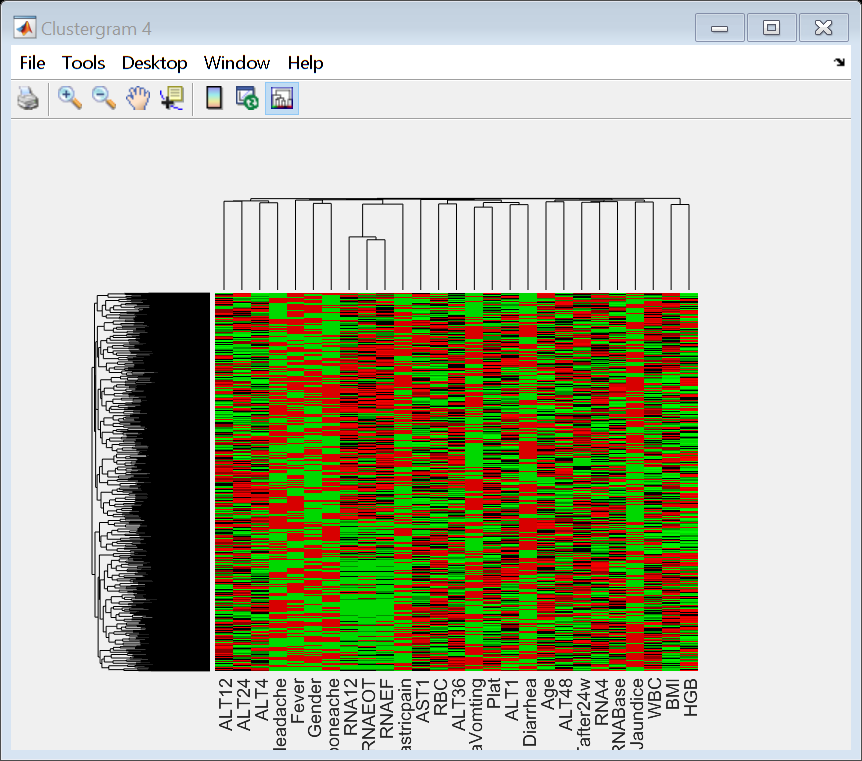

Clustergram object with 1385 rows of nodes and 27 columns of nodes.



gscatter(HCV1_array(:,24),HCV1_array(:,27),T)
cutoff = median([z(1381,3) z(1382,3)]);
dendrogram(z,'ColorThreshold',cutoff)
lastThree = [z(end-2:end,1) z(end-2:end,2)]

2768 cluster combines with cluster 2766(red)

2768 cluster is formed by combining 2765(green) and 2767

2767 cluster is fromed by combining 2761(purple) and 2764(light blue)

% Using removed outliers data
[b,dev,stats]=mnrfit(array_out(:,8),array_out_s)

dat =     0.8000         0    1.0000    1.0000         0         0         0    1.0000    1.0000    1.0000    0.5000         0    0.2500    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0    1.0000    1.0000    1.0000         0         0
    0.4000         0    0.3333         0    1.0000    1.0000         0    1.0000    1.0000         0    1.0000         0         0    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000         0    0.6667    1.0000    1.0000    1.0000    1.0000         0         0         0    0.5000         0         0    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0    1.0000    1.0000         0    1.0000    1.0000
    0.6000    1.0000    0.6667         0    1.0000         0    1.0000         0    1.0000         0    0.5000         0    0.7500    1.0000    1.0000    1.0000    1.0000    1.0000 

stats.p

ans =    -0.0138   -0.0138
    0.0120    0.0120
   -0.0686   -0.0686
   -0.0310   -0.0310
    0.0549    0.0549
   -0.0020   -0.0020
   -0.0056   -0.0056
    0.0146    0.0146
    0.0202    0.0202
   -0.0521   -0.0521


X=array_out
z=linkage(X,'ward')
T = cluster(z,'maxclust',4)
accuracy=sum(T==array_out_s)/length(array_out_s)
gscatter(X(:,end-2),X(:,end),T)
cutoff = median([z(end-3,3) z(end-1,3)]);
dendrogram(z,'ColorThreshold',cutoff)
lastThree = [z(end-2:end,1) z(end-2:end,2)]

dat =     0.0010    0.0005    0.0011    0.0010    0.0005    0.0005    0.0005    0.0010    0.0010    0.0010    0.0007    0.0007    0.0005    0.0008    0.0007    0.0007    0.0007    0.0007    0.0007    0.0002    0.0002    0.0003    0.0007    0.0007    0.0008    0.0004    0.0004
    0.0006    0.0005    0.0007    0.0005    0.0010    0.0010    0.0005    0.0010    0.0010    0.0005    0.0011    0.0007    0.0002    0.0008    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0010    0.0007    0.0007    0.0008    0.0008    0.0008
    0.0011    0.0005    0.0009    0.0010    0.0010    0.0010    0.0010    0.0005    0.0005    0.0005    0.0007    0.0007    0.0002    0.0008    0.0007    0.0007    0.0007    0.0007    0.0007    0.0002    0.0002    0.0003    0.0007    0.0007    0.0004    0.0008    0.0008
    0.0008    0.0010    0.0009    0.0005    0.0010    0.0005    0.0010    0.0005    0.0010    0.0005    0.0007    0.0007    0.0010    0.0008    0.0007    0.0007    0.0007    0.0007 

dat=normalize(HCV1_array(:,1:27),'range')
funccorr=pdist(dat.(27),'seuclidean')

ans =    -0.0138   -0.0138
    0.0120    0.0120
   -0.0686   -0.0686
   -0.0310   -0.0310
    0.0549    0.0549
   -0.0020   -0.0020
   -0.0056   -0.0056
    0.0146    0.0146
    0.0202    0.0202
   -0.0521   -0.0521


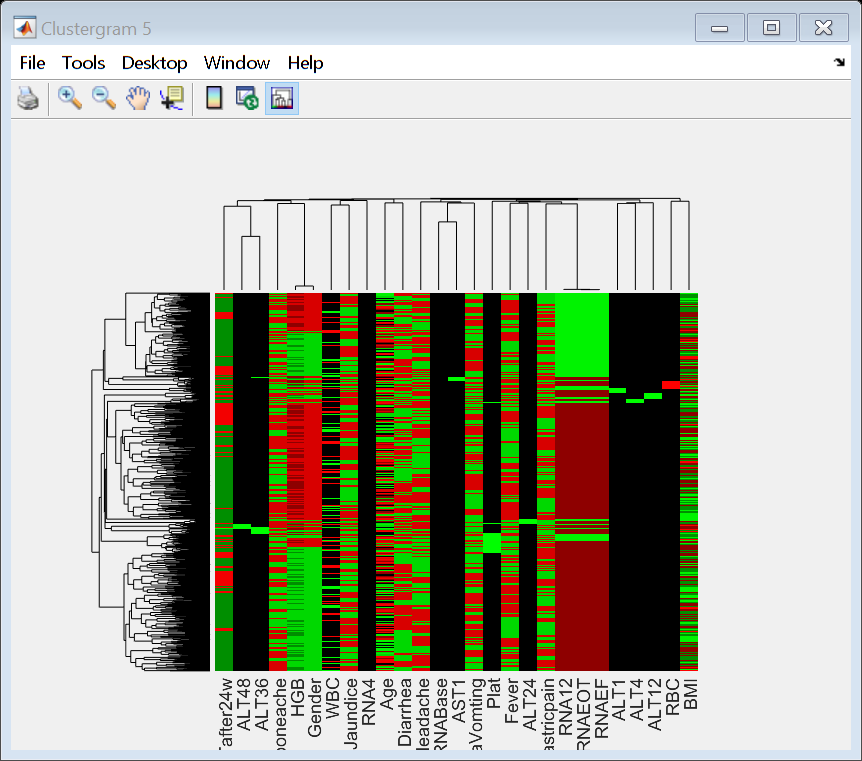

Clustergram object with 1385 rows of nodes and 27 columns of nodes.



z=linkage(funccorr)
dendrogram(z)

v=1:5
normalize(v,'norm',1)

dat =     0.8276    1.0000    0.4867    0.3597    0.8000    0.1433    0.6742    0.5056    0.1461    0.7865    0.4719         0         0         0    0.5456    0.5280    0.0772         0         0
    0.4828    0.5385    1.0000    0.5100         0    0.2724    0.5843    0.9438    0.6292    0.4045    0.8315    0.4228    0.9593    0.9750    0.0338    0.4482    0.1707    0.4166    0.0384
    0.8621    0.8462    0.1303    0.6695    0.4000    0.4384    0.8315    0.1124    0.6292    0.7640    0.8652         0         0         0    0.4755    0.5503         0    0.9103    0.6896
    0.5862    0.8462    0.3841    0.8138         0    0.4005    0.0449    0.2809    0.7865    0.4607    0.5506    0.3496    0.5854    0.7000    0.8675    0.3744    0.1570    0.9209    0.7186
    0.9310    0.7692    0.0735    0.6572    0.2000    0.7094    0.6742    0.7303    0.3146    0.1011    0.9101    0.7236    0.6911    0.6250    0.5498    0.6147    1.0000    0.4193    0.2997
    0.8966         0    0.9653    0.054

[normalize(HCV1_array(:,1),'norm',1) normalize(HCV1_array(:,25),'norm',1)]
[normalize(HCV1_array(:,1),'range') normalize(HCV1_array(:,25),'range')] % better

ans =    -0.0196   -0.0196
   -0.0573   -0.0573
    0.0179    0.0179
    0.0096    0.0096
    0.0028    0.0028
   -0.0173   -0.0173
   -0.0251   -0.0251
    0.0369    0.0369
   -0.0150   -0.0150
    0.0008    0.0008


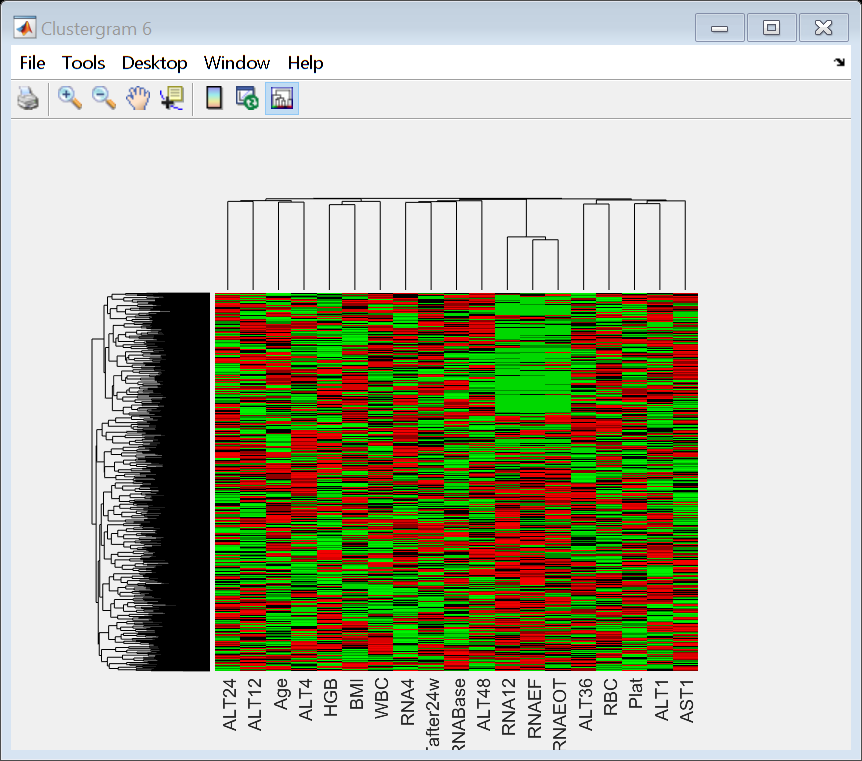

Clustergram object with 1385 rows of nodes and 19 columns of nodes.



dat=normalize(HCV1_array(:,1:27),'range')
disease_severity=HCV1.Baselinehistologicalstaging;
[corr(dat,disease_severity) corr(HCV1_array(:,1:27),disease_severity)] %same
fram_cg_corr=clustergram(dat,...
    'RowLabels',disease_severity,....
    'ColumnLabels',col_names,...

    'Standardize','column',....
    'RowPdist','correlation',....

dat =     0.8000    1.0000    0.5000         0    0.2500    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0    1.0000    1.0000    1.0000         0         0
    0.4000    0.3333    1.0000         0         0    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    0.6667    0.5000         0         0    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0    1.0000    1.0000         0    1.0000    1.0000
    0.6000    0.6667    0.5000         0    0.7500    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.5000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    0.6667         0         0         0    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.5000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000         0    1.0000         

    'ColumnPdist','correlation')

dat=normalize(HCV_array(:,1:27),'range')

ans =    -0.0138   -0.0138
   -0.0686   -0.0686
    0.0260    0.0260
   -0.0276   -0.0276
    0.0114    0.0114
    0.0163    0.0163
    0.0035    0.0035
    0.0093    0.0093
   -0.0433   -0.0433
    0.0247    0.0247


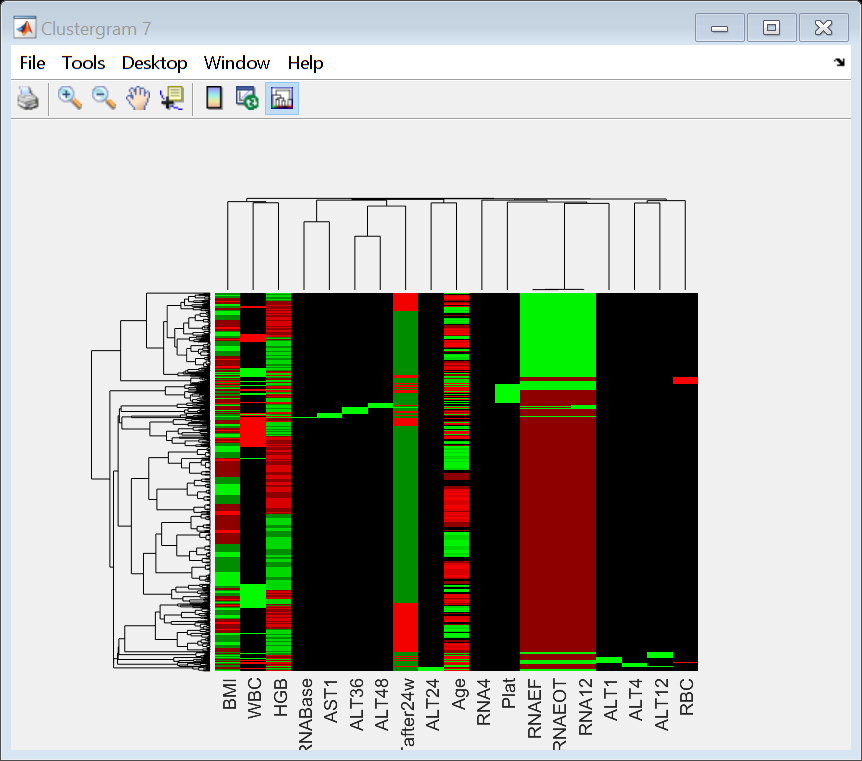

Clustergram object with 1385 rows of nodes and 19 columns of nodes.



disease_severity=HCV1.Baselinehistologicalstaging;
[corr(dat,disease_severity) corr(HCV_array(:,1:27),disease_severity)] %same
fram_cg_corr=clustergram(dat,...
    'RowLabels',disease_severity,....
    'ColumnLabels',col_names,...
    'Standardize','column',....

    'RowPdist','correlation',....
    'ColumnPdist','correlation')

dat=normalize(HCV_array(:,1:27),'norm',1)
disease_severity=HCV1.Baselinehistologicalstaging;
[corr(dat,disease_severity) corr(HCV_array(:,1:27),disease_severity)] %same
fram_cg_corr=clustergram(dat,...
    'RowLabels',disease_severity,....
    'ColumnLabels',col_names,...
    'Standardize','column',....
    'RowPdist','correlation',....
    'ColumnPdist','correlation')

% Exclude categorical data
col_names1=HCV1.Properties.VariableNames([1,3,11:27]);
dat=normalize(HCV1_array(:,[1,3,11:27]),'range')
disease_severity=HCV1.Baselinehistologicalstaging;
[corr(dat,disease_severity) corr(HCV1_array(:,[1,3,11:27]),disease_severity)] %same
fram_cg_corr=clustergram(dat,...
    'RowLabels',disease_severity,....
    'ColumnLabels',col_names1,...
    'Standardize','column',....
    'RowPdist','correlation',....
    'ColumnPdist','correlation')

dat=normalize(HCV_array(:,[1,3,11:27]),'range')
disease_severity=HCV1.Baselinehistologicalstaging;
[corr(dat,disease_severity) corr(HCV_array(:,[1,3,11:27]),disease_severity)] %same
fram_cg_corr=clustergram(dat,...
    'RowLabels',disease_severity,....
    'ColumnLabels',col_names1,...
    'Standardize','column',....
    'RowPdist','correlation',....
    'ColumnPdist','correlation')

# Clustogram

disease_severity=HCV1.Baselinehistologicalstaging;
fram_cg_corr=clustergram(HCV_array(:,1:27),...
    'RowLabels',disease_severity,....
    'ColumnLabels',col_names,...
    'Standardize','column')

disease_severity=HCV1.Baselinehistologicalstaging;
fram_cg_corr=clustergram(HCV1_array(1:100,1:27),...
    'RowLabels',disease_severity(1:100),....
    'ColumnLabels',col_names,...
    'Standardize','column',....
    'RowPdist','correlation',....
    'ColumnPdist','correlation')

disease_severity=HCV1.Baselinehistologicalstaging;
fram_cg_corr=clustergram(HCV_array(1:100,1:27),...
    'RowLabels',disease_severity(1:100),....
    'ColumnLabels',col_names,...
    'Standardize','column')